clear all; close all
syms t theta x y

%trajectory
xr0 = 1;
yr0 = 2;
a = 1;
b = pi;
c = 0.2;

xr = xr0 + a * t %prescribed x 

$$xr = t+1$$

dxr = diff(xr,t)%prescribed velocity

$$dxr = 1$$

yr = yr0 + c * sin(b*t)%prescribed y

$$yr = \frac{\sin\left(\pi \,t\right)}{5}+2$$

dyr = diff(yr,t) %prescribed velocity y

$$dyr = \frac{\pi \,\cos\left(\pi \,t\right)}{5}$$

theta_r = atan(dyr/dxr) %prescribed angle

$$theta\_r = \mathrm{atan}\left(\frac{\pi \,\cos\left(\pi \,t\right)}{5}\right)$$

dtheta_r = diff(theta_r,t) %prescribed angular velocity

$$dtheta\_r = -\frac{\pi^{2}\,\sin\left(\pi \,t\right)}{5\,\left(\frac{\pi^{2}\,{\cos\left(\pi \,t\right)}^{2}}{25}+1\right)}$$

%angle control
c_1 = 10; %feedback gain
omega_r = dtheta_r;
omega_fb = c_1*sin(theta_r-theta)

$$omega\_fb = -10\,\sin\left(\theta -\mathrm{atan}\left(\frac{\pi \,\cos\left(\pi \,t\right)}{5}\right)\right)$$

omega = omega_r + omega_fb

$$omega = -10\,\sin\left(\theta -\mathrm{atan}\left(\frac{\pi \,\cos\left(\pi \,t\right)}{5}\right)\right)-\frac{\pi^{2}\,\sin\left(\pi \,t\right)}{5\,\left(\frac{\pi^{2}\,{\cos\left(\pi \,t\right)}^{2}}{25}+1\right)}$$


%speed control
c2 = 10;
c3 = 0.1;
vr = sqrt(dxr^2+dyr^2)

$$vr = \sqrt{\frac{\pi^{2}\,{\cos\left(\pi \,t\right)}^{2}}{25}+1}$$

vfb = c2 * (cos(theta) * (xr-x) + sin(theta) * (yr - y)) ...
    - c3*omega_r*(-sin(theta)*(xr-x)+cos(theta)*(yr-y))

$$vfb = \begin{array}{l} 10\,\sin\left(\theta \right)\,\sigma_{1}+10\,\cos\left(\theta \right)\,\left(t-x+1\right)+\frac{\pi^{2}\,\sin\left(\pi \,t\right)\,\left(\cos\left(\theta \right)\,\sigma_{1}-\sin\left(\theta \right)\,\left(t-x+1\right)\right)}{50\,\left(\frac{\pi^{2}\,{\cos\left(\pi \,t\right)}^{2}}{25}+1\right)}\\ \mathrm{where}\\ \sigma_{1}=\frac{\sin\left(\pi \,t\right)}{5}-y+2 \end{array}$$

v = vr + vfb

$$v = \begin{array}{l} 10\,\sin\left(\theta \right)\,\left(\frac{\sin\left(\pi \,t\right)}{5}-y+2\right)+\sqrt{\sigma_{1}}+10\,\cos\left(\theta \right)\,\left(t-x+1\right)+\frac{\pi^{2}\,\sin\left(\pi \,t\right)\,\left(\cos\left(\theta \right)\,\left(\frac{\sin\left(\pi \,t\right)}{5}-y+2\right)-\sin\left(\theta \right)\,\left(t-x+1\right)\right)}{50\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\frac{\pi^{2}\,{\cos\left(\pi \,t\right)}^{2}}{25}+1 \end{array}$$

v * cos(theta) 

$$ans = \begin{array}{l} \cos\left(\theta \right)\,\left(10\,\sin\left(\theta \right)\,\left(\frac{\sin\left(\pi \,t\right)}{5}-y+2\right)+\sqrt{\sigma_{1}}+10\,\cos\left(\theta \right)\,\left(t-x+1\right)+\frac{\pi^{2}\,\sin\left(\pi \,t\right)\,\left(\cos\left(\theta \right)\,\left(\frac{\sin\left(\pi \,t\right)}{5}-y+2\right)-\sin\left(\theta \right)\,\left(t-x+1\right)\right)}{50\,\sigma_{1}}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\pi^{2}\,{\cos\left(\pi \,t\right)}^{2}}{25}+1 \end{array}$$

omega %dtheta 

$$omega = -10\,\sin\left(\theta -\mathrm{atan}\left(\frac{\pi \,\cos\left(\pi \,t\right)}{5}\right)\right)-\frac{\pi^{2}\,\sin\left(\pi \,t\right)}{5\,\left(\frac{\pi^{2}\,{\cos\left(\pi \,t\right)}^{2}}{25}+1\right)}$$


dx = matlabFunction(v*cos(theta))

dx = function_handle with value:
    @(t,theta,x,y)cos(theta).*(sin(theta).*(-y+sin(t.*pi)./5.0+2.0).*1.0e+1+sqrt((pi.^2.*cos(t.*pi).^2)./2.5e+1+1.0)+cos(theta).*(t-x+1.0).*1.0e+1+(pi.^2.*sin(t.*pi).*(cos(theta).*(-y+sin(t.*pi)./5.0+2.0)-sin(theta).*(t-x+1.0)))./(pi.^2.*cos(t.*pi).^2.*2.0+5.0e+1))


dy = matlabFunction(v*sin(theta))

dy = function_handle with value:
    @(t,theta,x,y)sin(theta).*(sin(theta).*(-y+sin(t.*pi)./5.0+2.0).*1.0e+1+sqrt((pi.^2.*cos(t.*pi).^2)./2.5e+1+1.0)+cos(theta).*(t-x+1.0).*1.0e+1+(pi.^2.*sin(t.*pi).*(cos(theta).*(-y+sin(t.*pi)./5.0+2.0)-sin(theta).*(t-x+1.0)))./(pi.^2.*cos(t.*pi).^2.*2.0+5.0e+1))


d_theta = matlabFunction(omega)

d_theta = function_handle with value:
    @(t,theta)sin(theta-atan((pi.*cos(t.*pi))./5.0)).*-1.0e+1-(pi.^2.*sin(t.*pi))./((pi.^2.*cos(t.*pi).^2)./5.0+5.0)


%gain controller
%
f = @(t,x)[
    dx(t,x(3),x(1),x(2));
    dy(t,x(3),x(1),x(2));
    d_theta(t,x(3))
]

f = function_handle with value:
    @(t,x)[dx(t,x(3),x(1),x(2));dy(t,x(3),x(1),x(2));d_theta(t,x(3))]


%
%no gain controller
%{
f = @(t,x)[
    dx(t,x(3));
    dy(t,x(3));
    d_theta(t)
]
%}


tspan = [0 10];
x0 = [xr0 yr0 0]; %atan(yr0/xr0)
[T, X] = ode45(@(t,x)f(t,x),tspan,x0);
x_ref = arrayfun(matlabFunction(xr),T);
y_ref = arrayfun(matlabFunction(yr),T);
theta_ref = arrayfun(matlabFunction(theta_r),T);
X_ref = [x_ref y_ref theta_ref]

X_ref =     1.0000    2.0000    0.5610
    1.0000    2.0000    0.5610
    1.0000    2.0000    0.5610
    1.0000    2.0000    0.5610
    1.0000    2.0000    0.5610
    1.0001    2.0001    0.5610
    1.0001    2.0001    0.5610
    1.0002    2.0001    0.5610
    1.0002    2.0001    0.5610
    1.0005    2.0003    0.5610


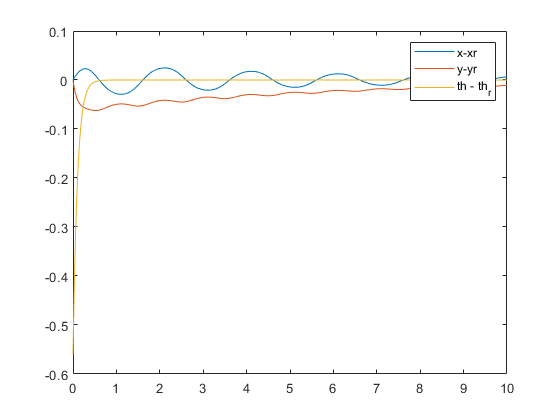

figure()
clf;
plot(T,X - X_ref)
legend('x-xr','y-yr', 'th - th_r')